clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')

% % Casts 
% cast01 = readSBScnv( 'ar69-01_001_hyst.cnv' );
% cast02 = readSBScnv( 'ar69-01_002_hyst.cnv');
% cast03 = readSBScnv( 'ar69-01_003_hyst.cnv' );
% cast04 = readSBScnv( 'ar69-01_004_hyst.cnv' );
% cast04b = readSBScnv( 'ar69-01_004b_hyst.cnv' );
% cast05 = readSBScnv( 'ar69-01_005_hyst.cnv' );
% cast06 = readSBScnv( 'ar69-01_006_hyst.cnv' );
cast07 = readSBScnv( 'ar69-01_007_hyst.cnv' );
cast08 = readSBScnv( 'ar69-01_008_hyst.cnv' );
cast09 = readSBScnv( 'ar69-01_009_hyst.cnv' );
cast10 = readSBScnv( 'ar69-01_010_hyst.cnv' );
cast11 = readSBScnv( 'ar69-01_011_hyst.cnv' );
cast12 = readSBScnv( 'ar69-01_012_hyst.cnv' );
cast13 = readSBScnv( 'ar69-01_013_hyst.cnv' );
cast14 = readSBScnv( 'ar69-01_014_hyst.cnv' );
cast15 = readSBScnv( 'ar69-01_015_hyst.cnv' );
cast16 = readSBScnv( 'ar69-01_016_hyst.cnv' );
cast17 = readSBScnv( 'ar69-01_017_hyst.cnv' );
cast18 = readSBScnv( 'ar69-01_018_hyst.cnv' );
cast19 = readSBScnv( 'ar69-01_019_hyst.cnv' );
cast20 = readSBScnv( 'ar69-01_020_hyst.cnv' );
cast21 = readSBScnv( 'ar69-01_021_hyst.cnv' );
cast22 = readSBScnv( 'ar69-01_022_hyst.cnv' );
cast23 = readSBScnv( 'ar69-01_023_hyst.cnv' );

% Casts 
% cast01 = readSBScnv( 'ar69-01_001_KFtest.cnv' );
% cast02 = readSBScnv( 'ar69-01_002_KFtest.cnv');
% cast03 = readSBScnv( 'ar69-01_003_KFtest.cnv' );
% cast04 = readSBScnv( 'ar69-01_004_KFtest.cnv' );
% cast04b = readSBScnv( 'ar69-01_004b_KFtest.cnv' );
% cast05 = readSBScnv( 'ar69-01_005_KFtest.cnv' );
% cast06 = readSBScnv( 'ar69-01_006_KFtest.cnv' );
% cast07 = readSBScnv( 'ar69-01_007_KFtest.cnv' );
% cast08 = readSBScnv( 'ar69-01_008_KFtest.cnv' );
% cast09 = readSBScnv( 'ar69-01_009_KFtest.cnv' );
% cast10 = readSBScnv( 'ar69-01_010_KFtest.cnv' );
% cast11 = readSBScnv( 'ar69-01_011_KFtest.cnv' );
% cast12 = readSBScnv( 'ar69-01_012_KFtest.cnv' );
% cast13 = readSBScnv( 'ar69-01_013_KFtest.cnv' );
% cast14 = readSBScnv( 'ar69-01_014_KFtest.cnv' );
% cast15 = readSBScnv( 'ar69-01_015_KFtest.cnv' );
% cast16 = readSBScnv( 'ar69-01_016_KFtest.cnv' );
% cast17 = readSBScnv( 'ar69-01_017_KFtest.cnv' );
% cast18 = readSBScnv( 'ar69-01_018_KFtest.cnv' );
% cast19 = readSBScnv( 'ar69-01_019_KFtest.cnv' );
% cast20 = readSBScnv( 'ar69-01_020_KFtest.cnv' );
% cast21 = readSBScnv( 'ar69-01_021_KFtest.cnv' );
% cast22 = readSBScnv( 'ar69-01_022_KFtest.cnv' );
% cast23 = readSBScnv( 'ar69-01_023_KFtest.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
btl = readtable('Irminger_Sea-09_AR69-01_CTD_Sampling_Summary_KF.xlsx','TextType','string');
btl.Cast = double(btl.Cast); btl.Bottle = double(btl.Bottle);
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);
btlsum14 = btl(btl.Cast == 14,:);
btlsum16 = btl(btl.Cast == 16,:);
btlsum17 = btl(btl.Cast == 17,:);
btlsum18 = btl(btl.Cast == 18,:);
btlsum19 = btl(btl.Cast == 19,:);
btlsum20 = btl(btl.Cast == 20,:);
btlsum21 = btl(btl.Cast == 21,:);


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year9')

% Bottle files processed with SBE E term of 0.036
btl07 = readtable('ar69-01_007_hyst.csv','TextType','string');

btl08 = readtable('ar69-01_008_hyst.csv','TextType','string');

btl09 = readtable('ar69-01_009_hyst.csv','TextType','string');

btl10 = readtable('ar69-01_010_hyst.csv','TextType','string');

btl11 = readtable('ar69-01_011_hyst.csv','TextType','string');

btl12 = readtable('ar69-01_012_hyst.csv','TextType','string');

btl13 = readtable('ar69-01_013_hyst.csv','TextType','string');

btl14 = readtable('ar69-01_014_hyst.csv','TextType','string');

btl16 = readtable('ar69-01_016_hyst.csv','TextType','string');

btl17 = readtable('ar69-01_017_hyst.csv','TextType','string');

btl18 = readtable('ar69-01_018_hyst.csv','TextType','string');

btl19 = readtable('ar69-01_019_hyst.csv','TextType','string');

btl20 = readtable('ar69-01_020_hyst.csv','TextType','string');

btl21 = readtable('ar69-01_021_hyst.csv','TextType','string');


% % Bottle files processed with E of 0.0383
% btl07 = readtable('ar69-01_007_KF.csv','TextType','string');
% btl08 = readtable('ar69-01_008_KF.csv','TextType','string');
% btl09 = readtable('ar69-01_009_KF.csv','TextType','string');
% btl10 = readtable('ar69-01_010_KF.csv','TextType','string');
% btl11 = readtable('ar69-01_011_KF.csv','TextType','string');
% btl12 = readtable('ar69-01_012_KF.csv','TextType','string');
% btl13 = readtable('ar69-01_013_KF.csv','TextType','string');
% btl14 = readtable('ar69-01_014_KF.csv','TextType','string');
% btl16 = readtable('ar69-01_016_KF.csv','TextType','string');
% btl17 = readtable('ar69-01_017_KF.csv','TextType','string');
% btl18 = readtable('ar69-01_018_KF.csv','TextType','string');
% btl19 = readtable('ar69-01_019_KF.csv','TextType','string');
% btl20 = readtable('ar69-01_020_KF.csv','TextType','string');
% btl21 = readtable('ar69-01_021_KF.csv','TextType','string');

% Join tables 
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum08 = join(btl08,btlsum08,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");
btlsum13 = join(btl13,btlsum13,'Keys',"Bottle");
btlsum14 = join(btl14,btlsum14,'Keys',"Bottle");
btlsum16 = join(btl16,btlsum16,'Keys',"Bottle");
btlsum17 = join(btl17,btlsum17,'Keys',"Bottle");
btlsum18 = join(btl18,btlsum18,'Keys',"Bottle");
btlsum19 = join(btl19,btlsum19,'Keys',"Bottle");
btlsum20 = join(btl20,btlsum20,'Keys',"Bottle");
btlsum21 = join(btl21,btlsum21,'Keys',"Bottle");

clear btl0* btl1* btl2*

btlsum_yr9 = [btlsum07; btlsum08; btlsum09; btlsum10; btlsum11; btlsum12; btlsum13;...
    btlsum14; btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21];

% Same Oxygen Sensor for whole cruise, except Cast 5 which fired no bottles  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.46780e-001);
cal.VOFFSET = double(-5.08600e-001);
cal.A = double(-5.00190e-003);
cal.B = double(2.51320e-004);
cal.C = double(-3.59380e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.22000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1960';
cal.OCALDATE = '31-Jul-21';

H = [-0.033, 5000, 1450]; % Default 

% Determine corrected E term
cal.E2 = 0.0384;
btlsum_yr9.tcorr = 1.0 + (cal.A.*btlsum_yr9.T090C) + (cal.B.*btlsum_yr9.T090C.^2) + (cal.C.*btlsum_yr9.T090C.^3);
btlsum_yr9.pcorr = exp((cal.E*btlsum_yr9.PrDM)./(btlsum_yr9.T090C + 273.15));
btlsum_yr9.pcorr2 = exp((cal.E2*btlsum_yr9.PrDM)./(btlsum_yr9.T090C + 273.15));
btlsum_yr9.SP = gsw_SP_from_C(btlsum_yr9.C0mS_cm,btlsum_yr9.T090C,btlsum_yr9.PrDM);
[btlsum_yr9.oxsol,~] = sbsoxygensol( btlsum_yr9.T090C, btlsum_yr9.SP, 'sbs' );

%Check that I am doing the math right SOC calc with E should == cal.SOC
SOCcalc = (btlsum_yr9.Sbeox0ML_L./(btlsum_yr9.oxsol.*btlsum_yr9.tcorr.*btlsum_yr9.pcorr))./(btlsum_yr9.Sbeox0V + cal.VOFFSET);
SOCwink = (btlsum_yr9.Winkler_mLL./(btlsum_yr9.oxsol.*btlsum_yr9.tcorr.*btlsum_yr9.pcorr))./(btlsum_yr9.Sbeox0V + cal.VOFFSET)

SOCwink =     0.4706
    0.4777
       NaN
       NaN
       NaN
       NaN
    0.4726
    0.4704
    0.4696
    0.4697


SOCwink2 = (btlsum_yr9.Winkler_mLL./(btlsum_yr9.oxsol.*btlsum_yr9.tcorr.*btlsum_yr9.pcorr2))./(btlsum_yr9.Sbeox0V + cal.VOFFSET)

SOCwink2 =     0.4572
    0.4642
       NaN
       NaN
       NaN
       NaN
    0.4643
    0.4621
    0.4641
    0.4641


SOCwink2_500 = (btlsum_yr9.Winkler_mLL(btlsum_yr9.PrDM > 500)./(btlsum_yr9.oxsol(btlsum_yr9.PrDM > 500).*btlsum_yr9.tcorr(btlsum_yr9.PrDM > 500).*btlsum_yr9.pcorr2(btlsum_yr9.PrDM > 500)))./(btlsum_yr9.Sbeox0V(btlsum_yr9.PrDM > 500) + cal.VOFFSET)

SOCwink2_500 =     0.4572
    0.4642
       NaN
       NaN
       NaN
       NaN
    0.4643
    0.4621
    0.4641
    0.4641


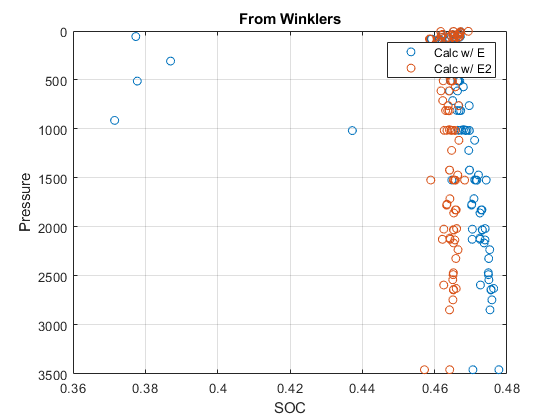


cutoff = nanmean(SOCwink2) - nanstd(SOCwink2)/3; 
SOCwink2(SOCwink < cutoff) = NaN; 

figure
plot(SOCwink,btlsum_yr9.PrDM,'o')
hold on
plot(SOCwink2,btlsum_yr9.PrDM,'o')
axis ij
grid on
ylabel('Pressure')
xlabel('SOC')
legend('Calc w/ E','Calc w/ E2','Location','NE')
title('From Winklers')

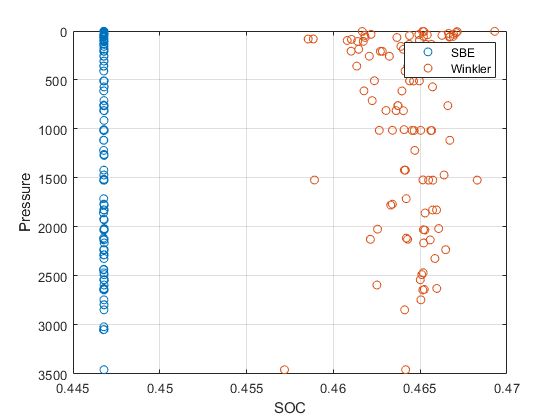


figure
plot(SOCcalc,btlsum_yr9.PrDM,'o')
hold on
plot(SOCwink2,btlsum_yr9.PrDM,'o')
axis ij
grid on
ylabel('Pressure')
xlabel('SOC')
legend('SBE','Winkler','Location','NE')


disp(['Gain = ' num2str(nanmean(SOCwink2./cal.SOC)) '+/- ' num2str(nanstd(SOCwink2./cal.SOC))])

Gain = 1.0391+/- 0.0045652


disp(['Gain_500 = ' num2str(nanmean(SOCwink2_500./cal.SOC)) '+/- ' num2str(nanstd(SOCwink2_500./cal.SOC))])

Gain = 1.032+/- 0.037156


% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;

cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);

Unrecognized function or variable 'cast01'.

cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);
cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);
cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);
cast04b = align_CTD_KF(cast04,'Cast 04b',a1,a2,a3);
cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);
cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);
cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);
cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);
cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);
cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);
cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);
cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);
cast13 = align_CTD_KF(cast13,'Cast 13',a1,a2,a3);
cast14 = align_CTD_KF(cast14,'Cast 14',a1,a2,a3);
cast15 = align_CTD_KF(cast15,'Cast 15',a1,a2,a3);
cast17 = align_CTD_KF(cast17,'Cast 17',a1,a2,a3);
cast18 = align_CTD_KF(cast18,'Cast 18',a1,a2,a3);
cast19 = align_CTD_KF(cast19,'Cast 19',a1,a2,a3);
cast20 = align_CTD_KF(cast20,'Cast 20',a1,a2,a3);
cast21 = align_CTD_KF(cast21,'Cast 21',a1,a2,a3);
cast22 = align_CTD_KF(cast22,'Cast 22',a1,a2,a3);
cast23 = align_CTD_KF(cast23,'Cast 23',a1,a2,a3);

% Pick align_sec

align_sec = 4;  % ***
% 
% cast01.DOv = SBE_alignCTDW(cast01.sbeox0V, align_sec, 1/24 );
% cast02.DOv = SBE_alignCTDW(cast02.sbeox0V, align_sec, 1/24 );
% cast03.DOv = SBE_alignCTDW(cast03.sbeox0V, align_sec, 1/24 );
% cast04.DOv = SBE_alignCTDW(cast04.sbeox0V, align_sec, 1/24 );
% cast05.DOv = SBE_alignCTDW(cast05.sbeox0V, align_sec, 1/24 );
% cast06.DOv = SBE_alignCTDW(cast06.sbeox0V, align_sec, 1/24 );
% cast07.DOv = SBE_alignCTDW(cast07.sbeox0V, align_sec, 1/24 );
% cast08.DOv = SBE_alignCTDW(cast08.sbeox0V, align_sec, 1/24 );
% cast09.DOv = SBE_alignCTDW(cast09.sbeox0V, align_sec, 1/24 );
% cast10.DOv = SBE_alignCTDW(cast10.sbeox0V, align_sec, 1/24 );
% cast11.DOv = SBE_alignCTDW(cast11.sbeox0V, align_sec, 1/24 );
% cast12.DOv = SBE_alignCTDW(cast12.sbeox0V, align_sec, 1/24 );


% H = [-0.02, 5000, 1850];
% align = 1; 
% [cast03] = adjust_hysteresis_KF(cast03,'Cast 03',H,cal,align);
% [cast04] = adjust_hysteresis_KF(cast04,'Cast 04',H,cal,align);
% [cast05] = adjust_hysteresis_KF(cast05,'Cast 05',H,cal,align);

cal.E2 = 3.83e-2;

addpath('G:\My Drive\Matlab_work\Functions\GSW')

btlsum07 = CTD_Gain_KF(btlsum07,cast07,'Cast 07',cal);
btlsum09 = CTD_Gain_KF(btlsum09,cast09,'Cast 09',cal);
btlsum10 = CTD_Gain_KF(btlsum10,cast10,'Cast 10',cal);
btlsum11 = CTD_Gain_KF(btlsum11,cast11,'Cast 11',cal);
btlsum12 = CTD_Gain_KF(btlsum12,cast12,'Cast 12',cal);
btlsum13 = CTD_Gain_KF(btlsum13,cast13,'Cast 13',cal);
btlsum14 = CTD_Gain_KF(btlsum14,cast14,'Cast 14',cal);
btlsum17 = CTD_Gain_KF(btlsum17,cast17,'Cast 17',cal);
btlsum18 = CTD_Gain_KF(btlsum18,cast18,'Cast 18',cal);
btlsum19 = CTD_Gain_KF(btlsum19,cast19,'Cast 19',cal);
btlsum21 = CTD_Gain_KF(btlsum21,cast21,'Cast 21',cal);



btlsum = [btlsum07; btlsum09; btlsum10; btlsum11;...
    btlsum12; btlsum13; btlsum14; btlsum17; btlsum18; btlsum19; btlsum21];

btlsum = [btlsum07; btlsum11;...
    btlsum12; btlsum13; btlsum14; btlsum17; btlsum18; btlsum19; btlsum21];

depth_cut = 500;

figure
plot(btlsum.gain,btlsum.PrDM,'*')
hold on
plot(btlsum.Egain,btlsum.PrDM,'ok')
% plot(btlsum.Egain(btlsum.PrDM > depth_cut),btlsum.PrDM(btlsum.PrDM > depth_cut),'ok')
axis ij
ylabel('Pressure (db)')
xlabel('Gain')
legend('Default E','Adjusted E','Location','SW')
grid on



disp(['Gain = ' num2str(nanmean(btlsum.gain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.gain(btlsum.PrDM > depth_cut)))])
disp(['EGain = ' num2str(nanmean(btlsum.Egain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.Egain(btlsum.PrDM > depth_cut)))])

figure
plot(btlsum.gain,btlsum.PrDM,'*')
hold on
plot(btlsum.Egain,btlsum.PrDM,'ok')
% plot(btlsum.Egain(btlsum.PrDM > depth_cut),btlsum.PrDM(btlsum.PrDM > depth_cut),'ok')
axis ij
ylabel('Pressure (db)')
xlabel('Gain')
legend('Default E','Adjusted E','Location','SW')
xlim([1.01 1.1])
grid on

disp(['Gain = ' num2str(nanmean(btlsum.gain(btlsum.PrDM > depth_cut & btlsum.gain >1.01))) '+/- ' num2str(nanstd(btlsum.gain(btlsum.PrDM > depth_cut & btlsum.gain >1.01)))])
disp(['EGain = ' num2str(nanmean(btlsum.Egain(btlsum.PrDM > depth_cut & btlsum.Egain >1.01))) '+/- ' num2str(nanstd(btlsum.Egain(btlsum.PrDM > depth_cut & btlsum.Egain >1.01)))])


cal.SOCnew = cal.SOC*nanmean(btlsum.Egain(btlsum.PrDM > depth_cut));
disp(['DO align (s) = ' num2str(align_sec)])
disp(['Cal. E term = ' num2str(cal.E)])
disp(['Adjust. E term = ' num2str(E2)])
disp(['Cal SOC = ' num2str(cal.SOC)])
disp(['New SOC = ' num2str(cal.SOCnew) ])


